A = double(imread('noether.jpg'));
size(A)

ans =    312   220


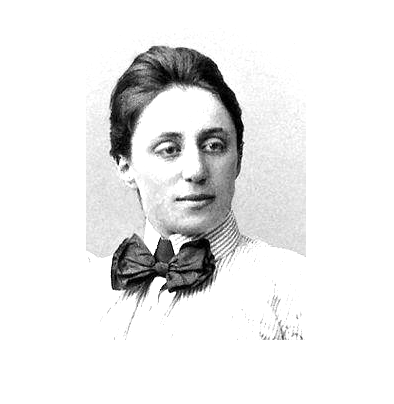

path='P:\EPFL\Troisième année\Semestre 2\Computationnal physics III\Third report\Week 12-13\Exercise2\figures\';
%path='Z:\Third report\Third report\Week 12-13\Exercise2\figures\';
% A=imshow('noether.jpg');
imshow(A*5e-3)

size(A)

ans =    312   220


[U,S,V]=svd(A);
size(U)

ans =    312   312


size(V)

ans =    220   220


length(diag(S))

ans = 220

find(diag(S)==0)


ans =

  0×1 empty double column vector



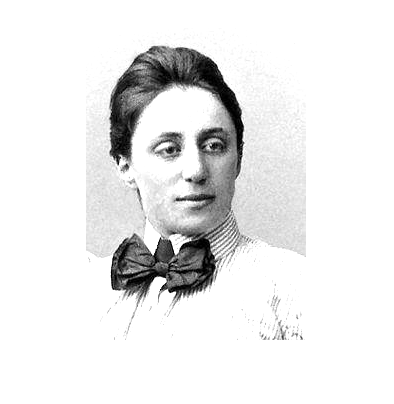

imshow(U*S*V'*5e-3)

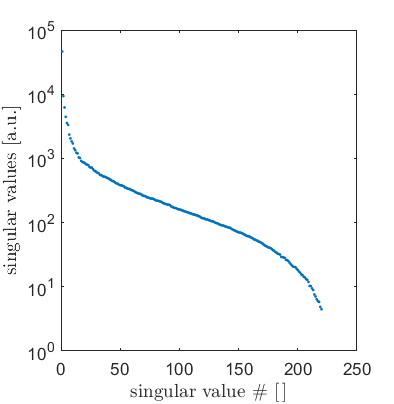

semilogy(1:size(S,2),diag(S)','.')
ylabel('singular values [a.u.]','Interpreter','latex','FontSize',18);
xlabel('singular value \# $\mathrm{[\,]}$','Interpreter','latex','FontSize',18);
set(gca,'FontSize',13)
saveas(gcf,strcat(path,'singularvalueslog'),'png');

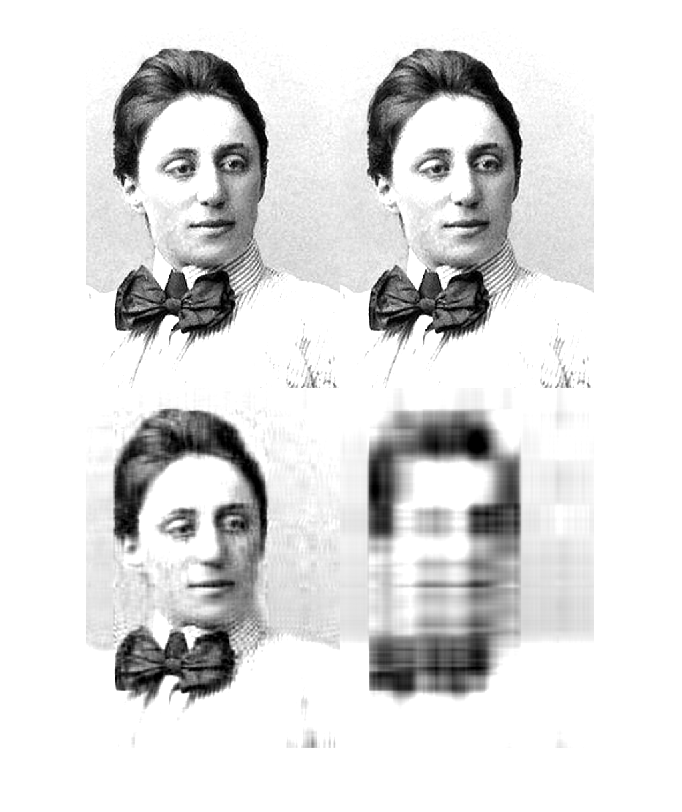

%the rank of the image is the number of non zero singular values
columnnum=size(S,2);
rownum=size(S,1);
sing=diag(S);
N=[rownum,100,20,4];
for i=1:4
    if N(i)<rownum
        S=diag([sing(1:N(i))', zeros(1,columnnum-N(i))]);
    else
        S=diag(sing);
    end
    S=[S;zeros(rownum-columnnum,columnnum)];
    onion(:,:,:,i) = U*S*V'*5e-3;
end
montage(onion,'size',[2 2]);
saveas(gcf,strcat(path,'compressedimages'),'png');

(312*311)/2+312+(220*219)/2+220

ans = 73138